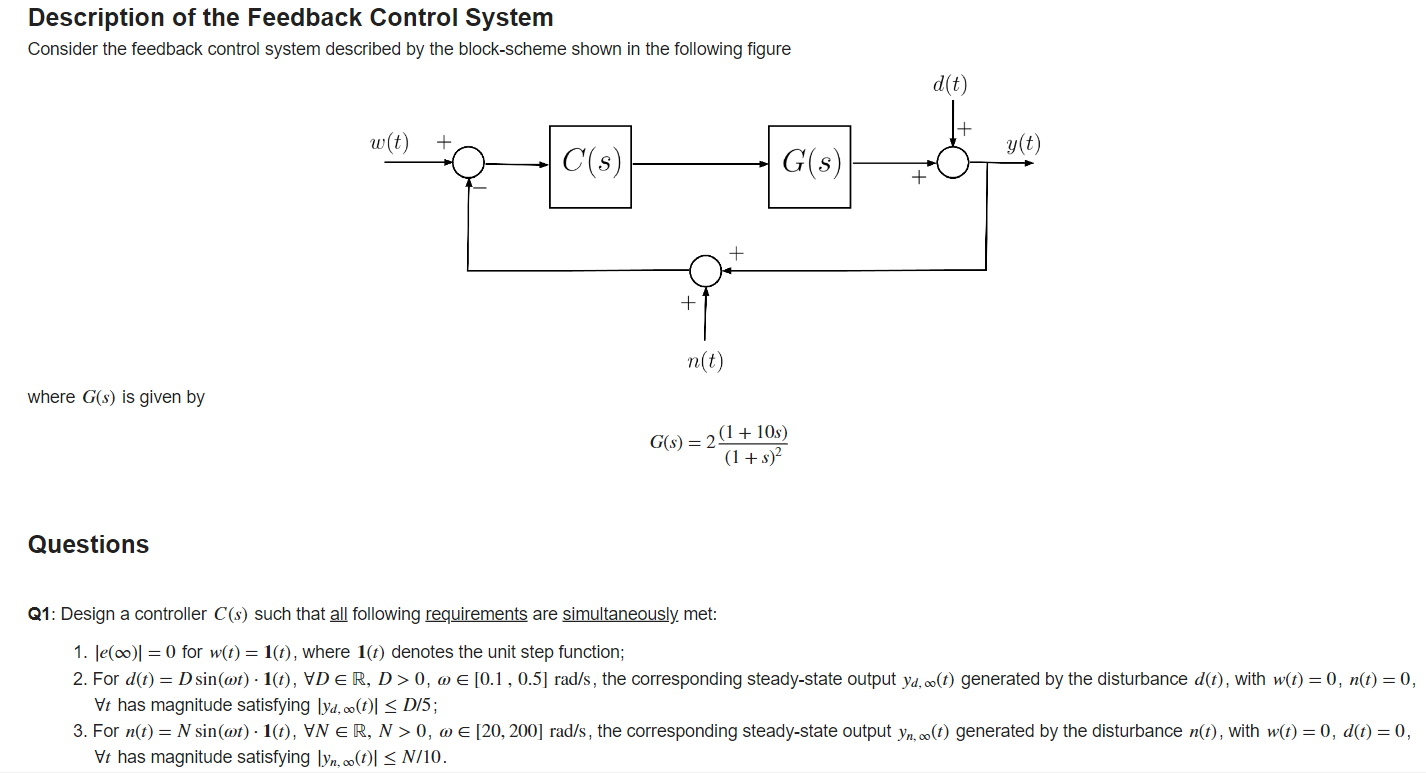

**ANALISI PRELIMINARE**

Il solo processo descritto dalla funzione di trasferimento G(s) porta ad un sistema con caratteristiche:

- margine di fase $\varphi_m = 95\degree $

- pulsazione critica $\omega_c = 20$ rad/s

- sistema di tipo 0

Ovviamente non soddisfa le specifiche. 

Progettiamo un regolatore della forma $C(s) = C_1(s) C_2(s)$ dove $C_1(s)$ è progettato per soddisfare la prima specifica (comportamento statico) e $C_2(s)$ è progettato per soddisfare la seconda e terza specifica (comportamento dinamico).

**PROGETTO STATICO **

Per rispettare il primo requisito (Q1.1) la funzione di trasferimento $L(s)$ deve essere di tipo $g \ge 1$. Consideriamo $g=1$ per tenere il controllore il più semplice possibile

Dunque, imponiamo $C_1(s) = \frac{\mu_c}{s}$ 

A questo punto, possiamo procedere a regolare il controllore in modo da rispettare anche gli altri requisiti.

**PROGETTO DINAMICO**

Il secondo requisito (Q1.2) riguarda la funzione di sensività $S(s)$, in dettaglio


$$\text{(Q1.2)} \; \Longleftrightarrow \; \left\vert S(j\, \omega ) \right \vert \le \frac{1}{5} \; \forall \omega \in \left[ 0.1,\,0.5 \right]\;\text{rad/s} \; \Longleftrightarrow \; 
\left\vert L(j\, \omega ) \right \vert \ge 5 = 14 \, \text{dB} \; \forall \omega \in \left[ 0.1,\,0.5 \right]\;\text{rad/s}$$


Il terzo requisito (Q1.3) riguarda la funzione di sensività complementare $F(s)$, in dettaglio 


$$\text{(Q1.3)} \; \Longleftrightarrow \; \left\vert F(j\, \omega ) \right \vert \le \frac{1}{10} \; \forall \omega \in \left[ 20,\,200\right]\;\text{rad/s} \; \Longleftrightarrow \; 
\left\vert L(j\, \omega ) \right \vert \le \frac{1}{10} = -20 \, \text{dB} \; \forall \omega \in \left[ 20,\,200\right]\;\text{rad/s}$$


Ricapitolando, abbiamo ottenuto i seguenti vincoli nella FdT $L(s)$ e nei diagrammi di Bode


$$\begin{array}{ccl}
\text{(Q1.1)} & :& L(s) = 2\mu_C\frac{(1+10\,s)}{s\,(1+s)^2} \\
\text{(Q1.2)} & :&  \left\vert L(j\,\bar \omega)\right\vert \ge 5,\; \forall \bar \omega \in \left[ \frac{1}{10},\;\frac{1}{2}\right] \quad \Longrightarrow \quad  \left\vert L(j\,\bar \omega)\right\vert \ge +14 \, \text{dB},\; \forall \bar \omega \in \left[ \frac{1}{10},\;\frac{1}{2}\right] \\
\text{(Q1.3)} & :&  \left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{10},\; \forall \bar \omega \in \left[ 20,\; 200\right] \quad \Longrightarrow \quad \left\vert L(j\,\bar \omega)\right\vert \le -20 \, \text{dB},\; \forall \bar \omega \in \left[ 20,\; 200\right] 
\end{array}$$


A questo punto, fissiamo il valore di $\mu_c = 1$ e aggiungiamo i vincoli nel Control System Desinger App

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



% Define the function G(s)

Gs = (2*(1+10*s))/(1+s)^2

Gs =
 
    20 s + 2
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties



% Define the controller G(s)

Cs = 1/s

Cs =
 
  1
  -
  s
 
Continuous-time transfer function.
Model Properties



controlSystemDesigner(Gs,Cs)